**Bode plot analysis:**

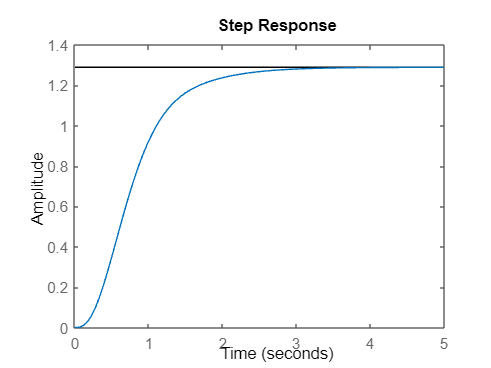

num = 49;
den = [1 8 32 38];
sys = tf (num,den);
step(sys);

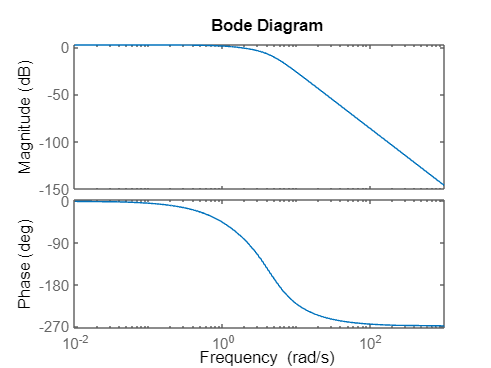

bode(sys);

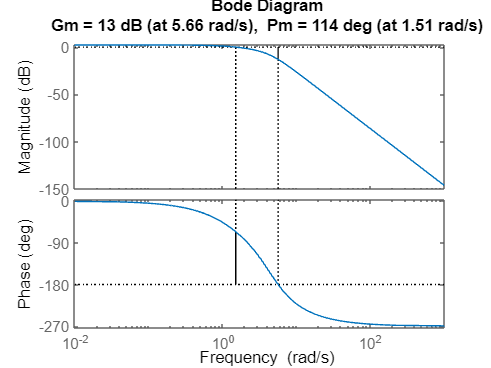

margin(sys)

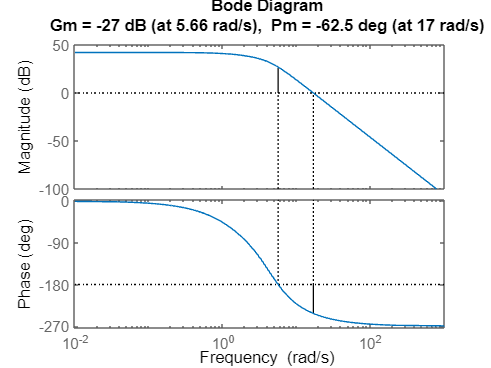

margin(100*sys);

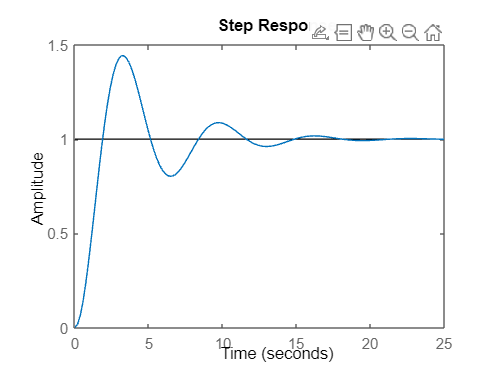

num = 1;
den = [1 0.5 1];

sys = tf(num,den);
step(sys);

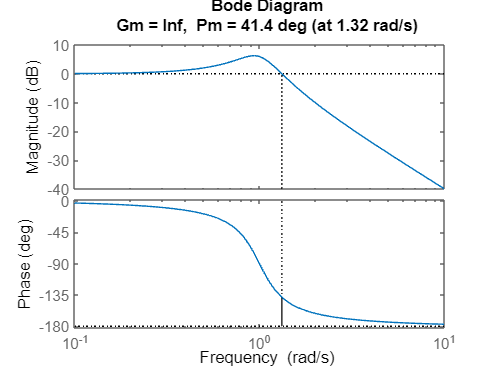

margin(sys);

w = -3

w = -3

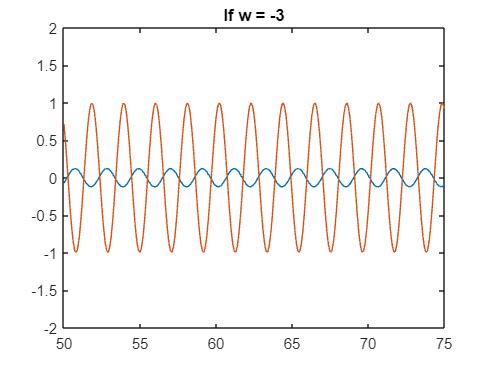

t = 0:0.1:100;

u = sin(w*t);
[y,t] = lsim(sys,u,t);

plot(t,y,t,u);

axis([50,75,-2,2]);
title('If w = -3');

 w = 1

w = 1

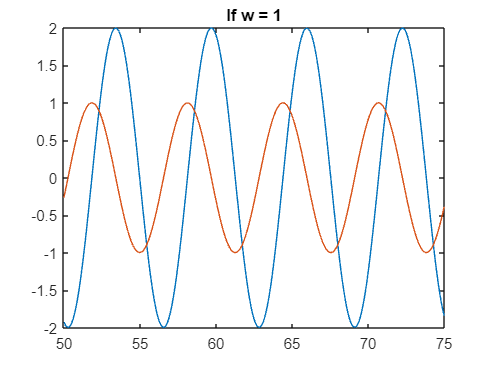

t = 0:0.1:100;

u = sin(w*t);
[y,t] = lsim(sys,u,t);

plot(t,y,t,u);

axis([50,75,-2,2]);
title('If w = 1');

w = 1.6

w = 1.6000

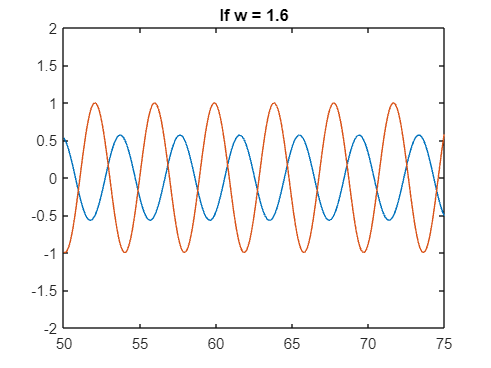

t = 0:0.1:100;

u = sin(w*t);
[y,t] = lsim(sys,u,t);

plot(t,y,t,u);

axis([50,75,-2,2]);
title('If w = 1.6');

w = 3

w = 3

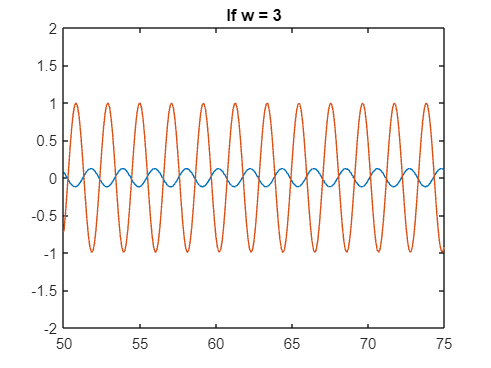

t = 0:0.1:100;

u = sin(w*t);
[y,t] = lsim(sys,u,t);

plot(t,y,t,u);

axis([50,75,-2,2]);
title('If w = 3');

**Example -3**

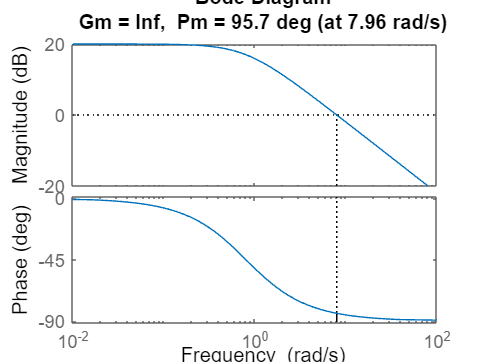

num = 10; 
den = [1.25 1]; 
sys = tf(num,den); 
margin(sys)

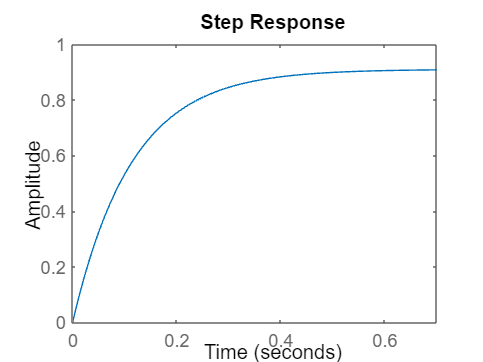

sys_cl = feedback(sys,1); 
step(sys_cl)

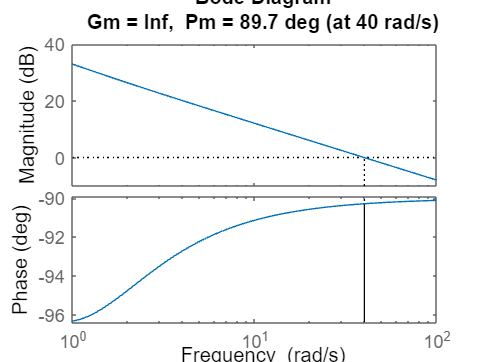

num = 10; 
den = [1.25 1]; 
plant = tf(num,den); 
numPI = 5*[1 1]; 
denPI = [1 0]; 
contr = tf(numPI,denPI); 
margin(contr * plant, logspace(0,2))

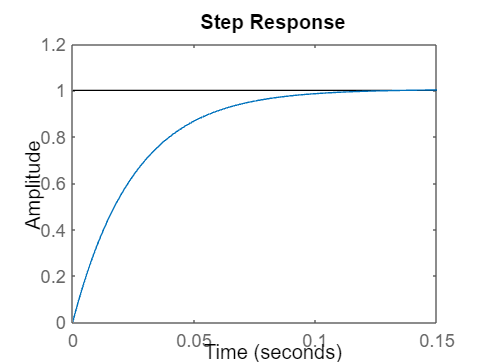

sys_cl = feedback(contr * plant,1); 
step(sys_cl)

Home Task - 2

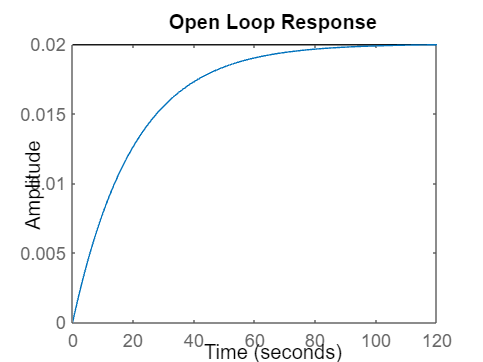

m=1000; 
b=50; 
u=10; 
num=[1]; 
den=[m b]; 
cruise=tf(num,den);
step(cruise);
title("Open Loop Response")

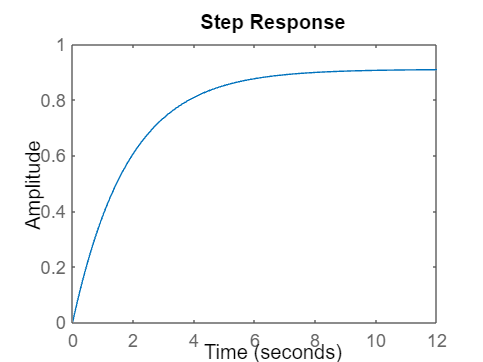

Kp = 500;
num_cl = Kp ;
den_cl = [m b+Kp];
cruise_cl = tf(num_cl,den_cl );
step(cruise_cl);

stepinfo(cruise_cl)

ans = struct with fields:
         RiseTime: 3.9946
    TransientTime: 7.1129
     SettlingTime: 7.1129
      SettlingMin: 0.8223
      SettlingMax: 0.9085
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9085
         PeakTime: 13.3131


desired_error = 0.02; 
Kp_min = (1 / desired_error) - 1;
disp(['Minimum Kp for desired steady-state error: ', num2str(Kp_min)]);

Minimum Kp for desired steady-state error: 49


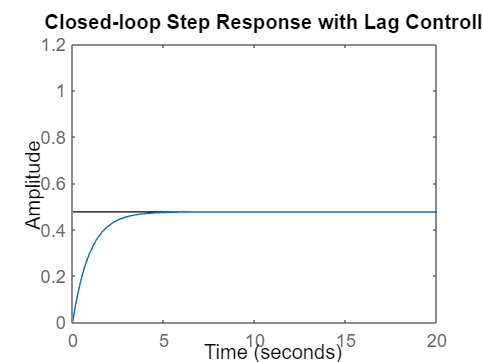

Zo = 0.00001;
Po = 0.000001;
lag_controller = tf([Zo, 1], [Po, 1]);

lag_compensated_tf = series(lag_controller, tf(Kp, [m, b + Kp]));
final_closed_loop_tf = feedback(lag_compensated_tf,1);


step(final_closed_loop_tf);
axis ([0 20 0 1.2]) 
title('Closed-loop Step Response with Lag Controller');

stepinfo(final_closed_loop_tf)

ans = struct with fields:
         RiseTime: 2.0924
    TransientTime: 3.7258
     SettlingTime: 3.7258
      SettlingMin: 0.4286
      SettlingMax: 0.4759
        Overshoot: 0
       Undershoot: 0
             Peak: 0.4759
         PeakTime: 6.9736
